# Simulate UAV Scenario Using Scenario Blocks

This example shows how to use the UAV scenario blocks to simulate a scenario in Simulink®.

## Create Scenario

Initialize your UAV scenario with meshes and [`uavPlatform`](docid:uav_ref#mw_d1b7e854-1260-4a1a-9594-dacf0a3e4b36) objects for the UAV Scenario blocks to use.

% Initialize the scenario 
scene = uavScenario(UpdateRate=100,ReferenceLocation=[0 0 0]);

%Create a ground for visualization
addMesh(scene,"polygon",{[-15 -15; 15 -15; 15 15; -15 15] [-0.5 0]},[0.3 0.3 0.3]);

% Add cylinder meshes to scan with lidar sensor
addMesh(scene,"cylinder",{[-5 5 2],[0 12]},[0 1 0]);
addMesh(scene,"cylinder",{[5 5 2],[0 12]},[0 1 0]);
addMesh(scene,"cylinder",{[5 -5 2],[0 12]},[0 1 0]);

Create one UAV platform to be controlled and another to be stationary.

% Platform/UAV initial position and orientation
initpos = [0 0 -5]; % NED Frame
initori = [0 0 0];

% Add two UAV Platform to the scenario and scale them for easier visualization
platform = uavPlatform("platformUAV",scene,ReferenceFrame="NED",...
    InitialPosition=initpos,InitialOrientation=eul2quat(initori));

updateMesh(platform,"quadrotor",{2},[0 0 0],eul2tform([0 0 pi]));

Create a [`uavSensor`](docid:uav_ref#mw_7c88aaf7-441c-4b43-8e22-cd19c7eaeae2) with a lidar sensor model using the [`uavLidarPointCloudGenerator`](docid:uav_ref#mw_7f07a187-0a5b-4716-9241-5cbf56226bed) and attach it to the first UAV platform. This sensor will be used in the Simulink simulation but the specifications of the lidar should be specified in the [UAV Scenario Lidar](docid:uav_ref#mw_7b3fe2b2-e216-4480-809c-7c089b5a7057) block because they will not be loaded into the model. 

LidarModel = uavLidarPointCloudGenerator();
uavSensor("Lidar",platform,LidarModel,"MountingLocation",[0,0,1],"MountingAngles",[0 0 180]);

## Configure the Scenario

open_system("UAVScenarioModel.slx")

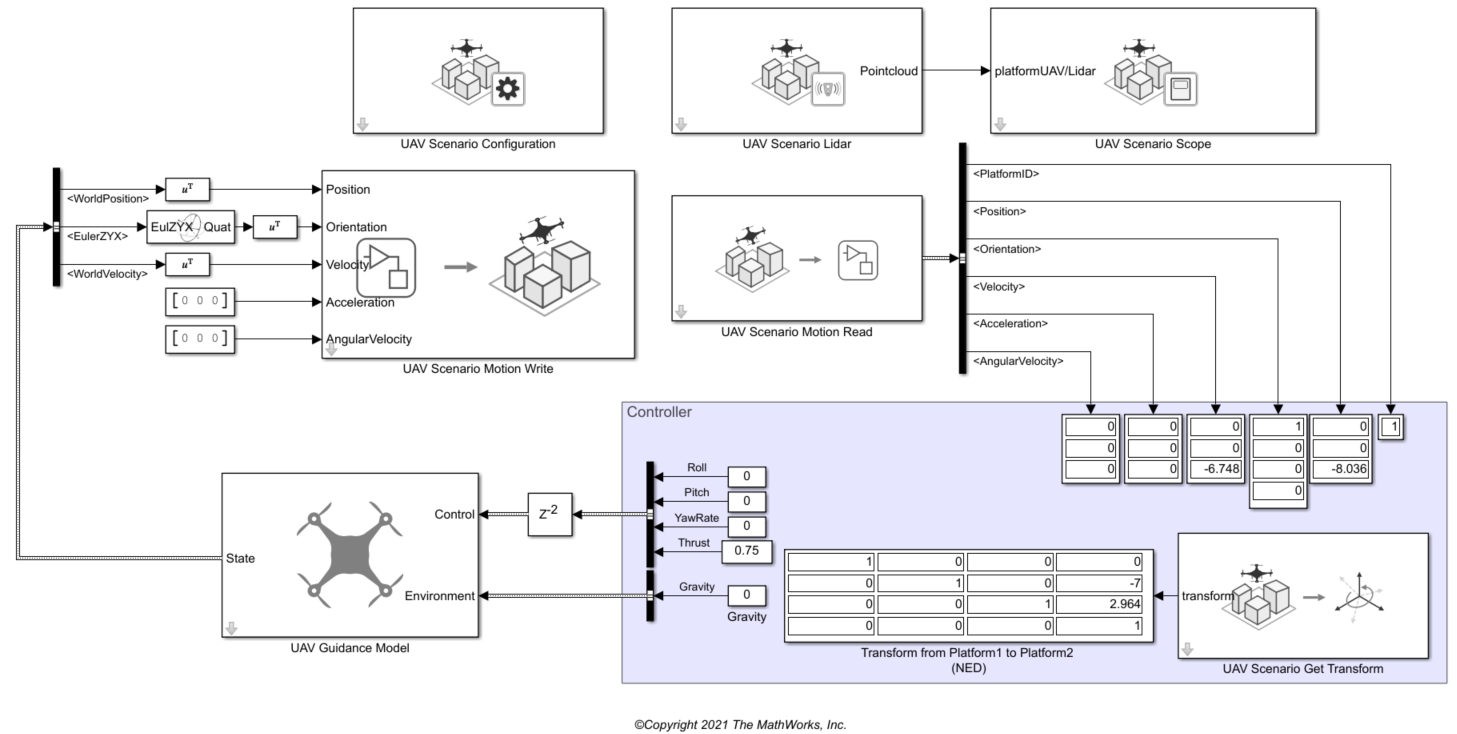

The [UAV Scenario Configuration](docid:uav_ref#mw_c639ebae-30ad-4c78-a760-a42b44f7379d) block is essential to simulating the UAV scenario in Simulink and must execute first. Place it in the model and set the `MATLAB or model workspace variable name` to the name of your scenario. Open this block and click **Refresh** whenever the scenario scene is changed in MATLAB to reflect those changes in Simulink. Change the sample time, and bus and signal names as necessary.

## Write to Motion Bus

Use the [UAV Scenario Motion Write](docid:uav_ref#mw_c15c8477-a5ca-4cdf-8b6c-badda3bf2b76) block to update the Motion bus of the first platform UAV. This will update the position of the UAV in the [UAV Scenario Scope](docid:uav_ref#mw_0fc36b77-a571-4c78-8b3f-0379b0f162e7) block simulation. Open the block and click **Select** to choose the first platform UAV. This is the platform UAV that we will be updating with this block.

This example uses a multirotor guidance model with constant inputs as the plant to determine the next position to write to the motion bus. However, any kind of plant or controller can be used to update the motion bus of the platform if you can extract inputs to be used in the UAV Scenario Motion Write block.

## Read from Motion Bus

After writing to the motion bus with the UAV Scenario Motion Write block, the motion block can be read using the [UAV Scenario Motion Read](docid:uav_ref#mw_5a35d72d-9d40-436e-b015-3f8f335a1d0d) block. This data can be used in your controller it determine the inputs to your plant. This example does not use a controller so the outputs are read into Display blocks. Open the block and click **Select** to choose the same UAV as you selected in the UAV Scenario Motion Write block.

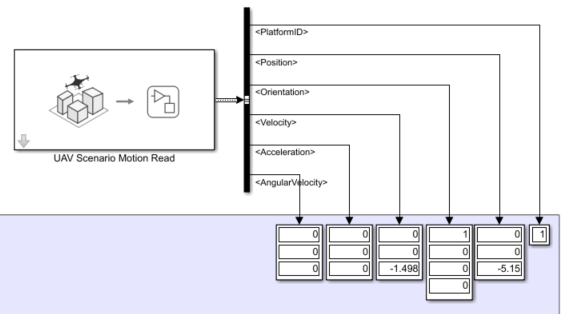

## Get Transform

Use the [UAV Scenario Get Transform](docid:uav_ref#mw_9e36e42a-70d9-4224-b537-25f09fed5b91) block to get the transformation matrix between the two UAVs. Open the block and set the `Source Frame` to the first UAV and the `Target Frame` to the second UAV.

 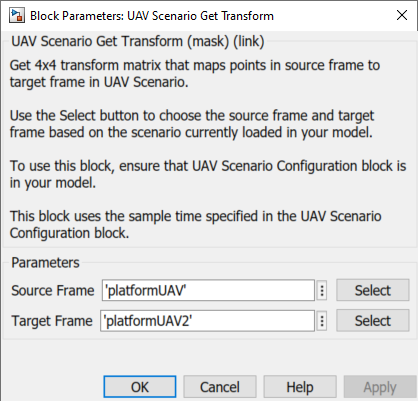

The transformation matrix in this example is displayed in a Display block, however the transformation data could have many applications in a controller.

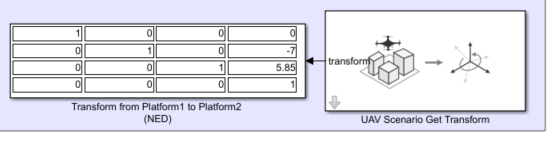

## View and Simulate Lidar

Use the UAV Scenario Lidar Block to use the lidar sensor created in the scenario. Open the block and specify the `Sensor name` by clicking the **Select** to choose the lidar sensor in the scene. The settings of the lidar can be edited by specifying the parameters in the block. 

 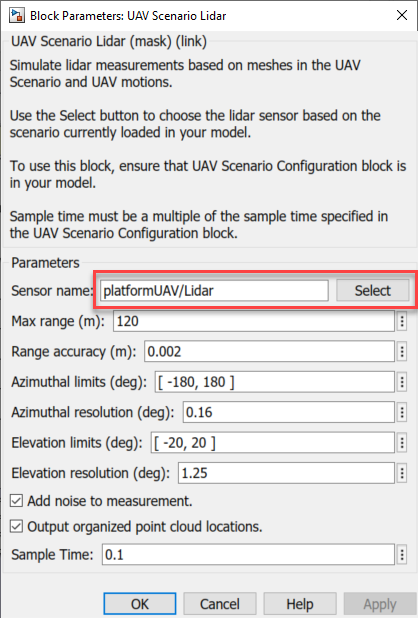

To visualize the lidar readings and the motion of the UAV, connect the UAV Scenario Lidar block to a UAV Scenario Scope block. To do so, you need to create a port by enabling the visualization toggle for the sensors you would like to connect. If you recently added a lidar sensor but do not see it in the table, try clicking **Refresh** in your UAV Configuration block and **Refresh sensor table** in this block.

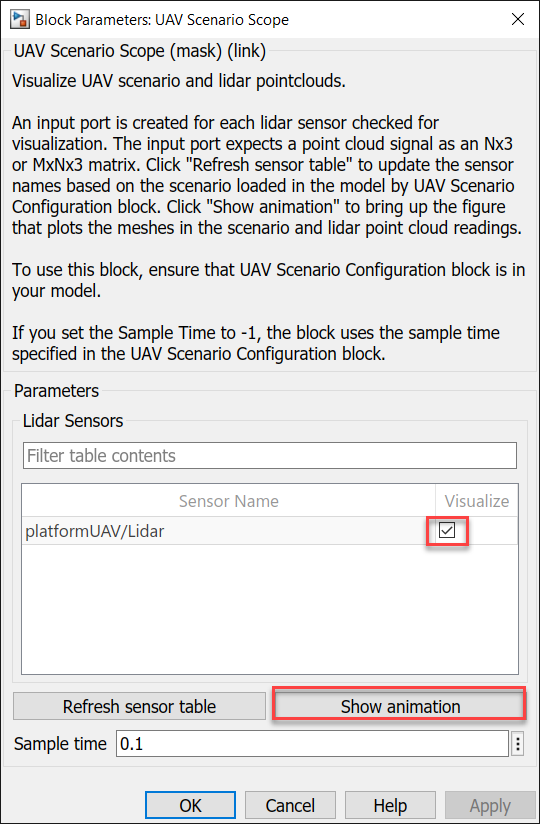

After enabling the visualization of the sensor, a port will appear on the UAV Scenario Scope block with the name of the platform and its sensor.

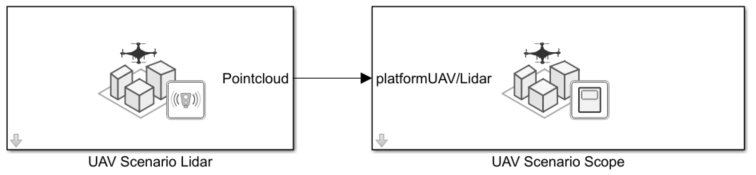

Click **Show animation** in the UAV Scenario Scope block to view the scenario, and run the model to see the animation.

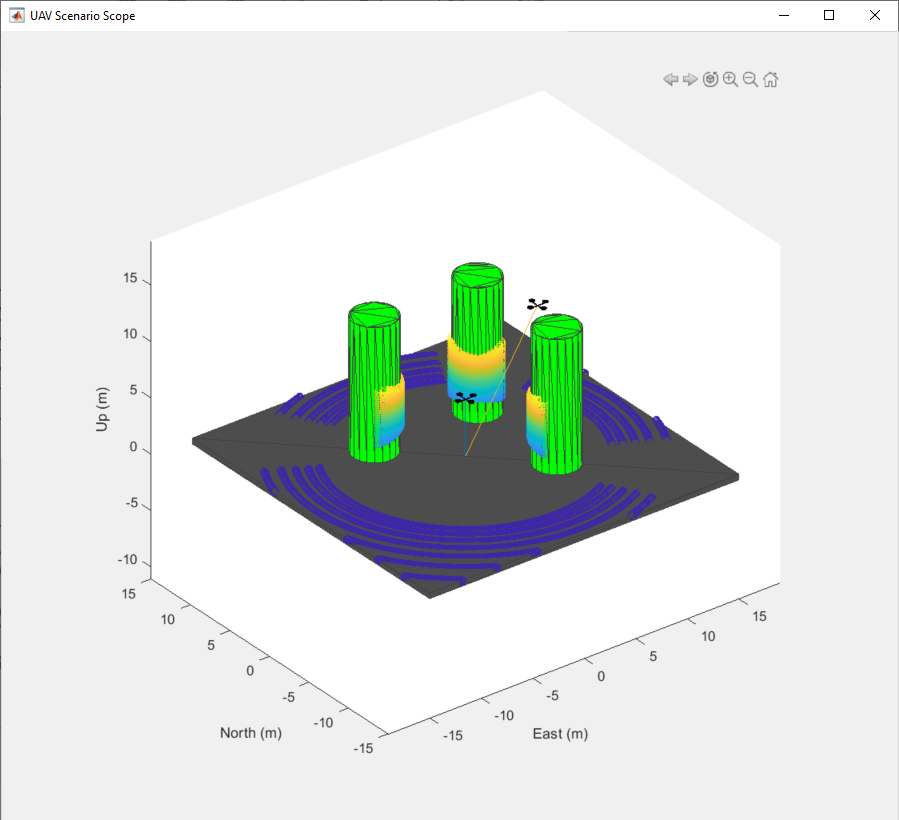

*Copyright 2021 The MathWorks, Inc.*

## Adesso iniziamo noi

prendo la nuvola di punti dal simulink che risulta essere una time series con le seguenti proprietà

            Time: [101x1 double]

            Data: [32x2250x3x101 double]

sono 32 scansioni verticali e 2250 orizzontali

il blocco UAV lidar  dice che

*"N*-by-*M*-by-3 double matrix, where *N* is the number of vertical scans, and *M* is the number of horizontal scans"

singleptcloud = pointCloud(out.nuvola.Data(:,:,:,1))

singleptcloud =   pointCloud with properties:

     Location: [32×2250×3 double]
        Count: 72000
      XLimits: [-15.0001 14.9996]
      YLimits: [-14.9967 14.9978]
      ZLimits: [-4.0022 2.5245]
        Color: []
       Normal: []
    Intensity: []


ptscloud = singleptcloud

ptscloud =   pointCloud with properties:

     Location: [32×2250×3 double]
        Count: 72000
      XLimits: [-15.0001 14.9996]
      YLimits: [-14.9967 14.9978]
      ZLimits: [-4.0022 2.5245]
        Color: []
       Normal: []
    Intensity: []


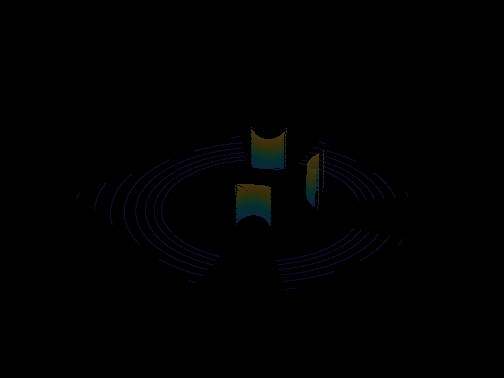

for i = 2:length(out.tout)
    ptscloud = [ptscloud pointCloud(out.nuvola.Data(:,:,:,i))];
end

pcshow(singleptcloud);% ne mostra solo uno alla volta

%[indices,dists] = findNeighborsInRadius(singleptcloud,[0 0 -5],10);
[indices,dists] = findNearestNeighbors(singleptcloud,[0 0 -5],100)

indices = 100×1 uint32 column vector
    9057
   44993
   26977
   26721
    8865
   27009
    8673
    9089
   44673
   44705


dists =     5.9856
    5.9866
    5.9871
    5.9871
    5.9872
    5.9874
    5.9875
    5.9876
    5.9877
    5.9877



newptCloudOut = select(singleptcloud,indices)

newptCloudOut =   pointCloud with properties:

     Location: [100×3 double]
        Count: 100
      XLimits: [-3.8134 3.8181]
      YLimits: [-3.7868 3.7681]
      ZLimits: [-1.8568 -1.8532]
        Color: []
       Normal: []
    Intensity: []


Posizione q_obstacle rispetto alla mappa 

vicinissimo = newptCloudOut.Location(1,:) 

vicinissimo =    -3.5815   -3.6192   -1.8532


Distanza rispetto all'origine

norm(vicinissimo) 

ans = 5.4185

Distanza rispetto al drone nell'istante in cui è generata la nuvola di punti

norm(vicinissimo-[0 0 -5]) 

ans = 5.9856

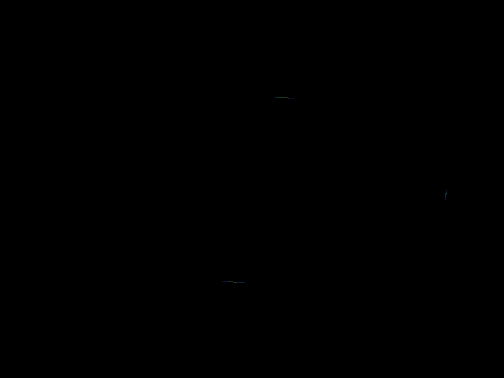

pcshow(newptCloudOut)